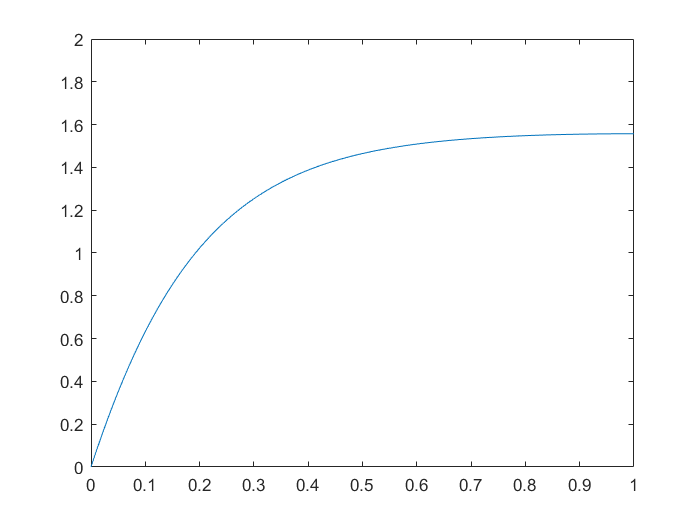

clc;
% Solving Beam ODE
B = 30;
C = 0;
S = 1;
P = 0;
Q = 0;
alpha = pi/2;
beta = pi/2;
th = 1;
Pi0 = 10000;
eps = 0;
epsilon = [];
Fz = C*sin(beta);
Fx = C*cos(beta);
j = 1;
xact = []; Thetact = [];

while eps <= 0.01
    xlow = 0; xhigh = 1;
    xmesh = linspace(xlow,xhigh,10);
    solinit = bvpinit(xmesh,@guess);
    opts = bvpset('RelTol',0.1,'AbsTol',0.1);
    sol = bvp4c(@(x,y) BeamODEfun(x,y,P,Q,C,S,alpha,beta,B,eps), @bc, solinit, opts);
    xint = linspace(xlow,xhigh,100);
    Sxint = deval(sol,xint);
    %axis([0 1 -2 2]);
    %plot(xint, Sxint(1,:));
    r = size(Sxint(1,:));
    temp = 10000000;
    x1 = 0; s1 = 0;
    for i = 1:r(2)
       del = delta(Pi0,eps,xint(i),Fx,Fz,Sxint(1,i),B,alpha,P,Q,S,th);
       if abs(del) < temp 
           temp = abs(del);
           x1 = xint(i);
           s1 = Sxint(1,i);
       end
    end
    xact(j) = x1;
    Thetact(j) = s1;
    epsilon(j) = eps;
    eps = eps + 0.00005;
    j = j+1;
end


%hold on;
%plot(xact, Thetact);
plot(xint, Sxint(1,:));
axis([0 1 0 2]);

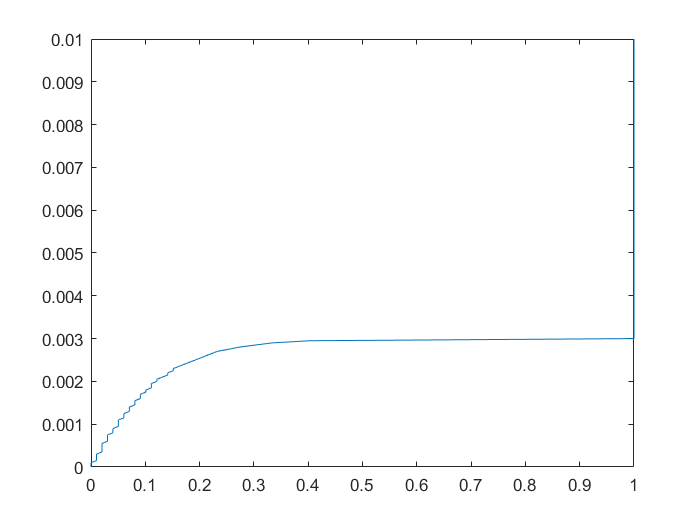

%title('Theta vs x');
%xlabel('x');
%ylabel('Theta');
%legend('C=1','C=3','C=5','C=7','C=10','C=20','C=40');


%hold on;
plot(xact, epsilon);
axis([0 1 0 0.01]);

%title('Epsilon vs x');
%xlabel('x');
%ylabel('Epsilon');
%legend('C=1','C=3','C=5','C=7','C=10','C=20','C=40');






